params.m1 = 5;
params.m2 = 5;

params.m5 = 60; % 5,1,1
params.m3 = params.m2;
params.m4 = params.m1;

params.l1 = 0.48;
params.l2 = 0.48;
params.l3 = params.l2;
params.l4 = params.l1;
params.l5 = 0.48;

params.g = 9.81;
params.I1 = 0.0960;
params.I2 = 0.0960;
params.I3 = params.I1;
params.I4 = params.I2;
params.I5 = 1.1520;

% biarticular muscle parameters

params.r = 1.6496; % dimensionless lever arm ratio (found from optimizing wrt SR) r = r_h / r_k
params.k_bar_ba = 63.8662; % [Nm] k_bar_ba = k_ba * r_k^2

params.r_k = 0.02; % [m] we choose this value and rest of the parameters are defined according to it and r, k_bar_ba
params.r_h = params.r*params.r_k; % [m]
% params.k_ba = params.k_bar_ba/(params.r_k^2); % [N/m]
params.k_ba = 0; % [N/m]
params.phi_h0 = pi; % [rad] free angle of springs at hip
params.phi_k0 = pi; % [rad] free angle of springs at knee

% SLIP Params
L_slip = 1; % [m]
alpha0 = 1.2; % angle at which swing leg touches the ground
k_slip = 15696; % nominal leg stiffness [N/m]
m_slip = 80; % hip mass [kg]

param = [params.m1; params.m2; params.m5; params.l1; params.l2; params.l5; params.g; params.I1; params.I2; params.I5; params.r_k; params.r_h; params.k_ba; params.phi_h0; params.phi_k0];

for i=1:length(time)
    CoM(i,:) = calculate_com(simout(i,:), param, 0, [0;0;0;0;0]);
end

dx_CoM = CoM(:,3);

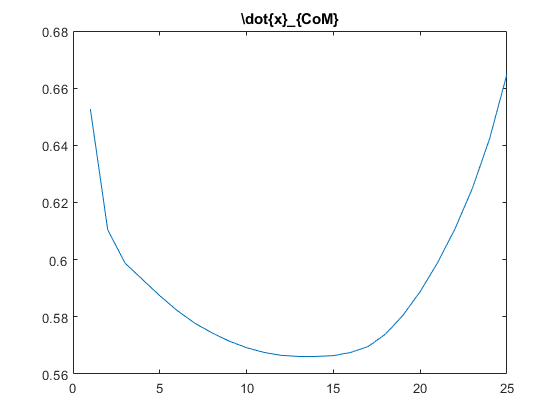

figure()
plot(dx_CoM)
title('\dot{x}_{CoM}')